# **Manifold paper analysis**

The script below runs the manifold paper analysis –excluding the potent/null space comparison– for a first set of parameters.

There are a few parameters that seem to be important:

- The **bin size**, and possibly the width of the smoothing kernel

- The (assumed) **dimensionality of the neural manifold**, i.e. the number of PCs that will be used to defined the neural manifold for each task. This same number be used to compute the angles between manifolds from different tasks, and also to compare task dynamics using CCA

- Whether we will define **the potent space **using EMGs, or a low dimensional representation (synergies) obtained with PCA or NMF. Note that Matt Tresch has [a simulation paper](http://jn.physiology.org/content/95/4/2199.short) that indicates that PCA fails to extract synergies, although I discussed it with him and he thinks it does capture the muscle space well. NMF, on the contrary, does capture the underlying synergies accurately, but has the downside of requiring the user to define a prior the number of synergies. 

-  When fitting the linear neuron-to-EMG model, the imposed lag of the EMGs/muscle synergies with respect to the neural activity.

# First run to generate presentation figures (12-09-2016)

These first chunks of code run the analysis with the following parameters:

- Bin size: 20 ms; Gaussian kernel SD: 50 ms

- Dimensionality of the neural manifold: 20

- Potent space: NMF, with 3 factors –Note that the EMG envelopes are always included, which means that we can switch back and forth easily for that

- Neural-to-EMG lag: 50 ms

## Step 1 –Preprocess the data

This code will load the data, bin and smooth it, do dimensionality reduction of the neurons (and EMGs if specified) and divide them in single trial data.

% go to the directory where the data are
cd('/Users/juangallego/Documents/NeuroPlast/Data/_Dimensionality reduction');

% -------------------------------------------------------------------------
% % 0. set some preprocessing parameters
prep_params                     = batch_preprocess_dim_red_data_params_defaults;
prep_params.bin_size            = .02;
prep_params.save_data           = false;
prep_params.norm_trial_data     = 'min_dur'; % 'min_dur' 't_warp'
prep_params.dim_red_emg         = 'nmf'; % 'nmf'
prep_params.emg_factors         = 3;

% preprocess the data
datasets                        = batch_preprocess_dim_red_data( pwd, prep_params );

 
preprocessing file all_tasks_Jaco_20110124.mat


Start time set to 0.0 seconds
Stop time set to 1200.00 seconds
Smoothing the firing rates...


Start time set to 0.0 seconds
Stop time set to 1200.00 seconds
Smoothing the firing rates...


 
 
preprocessing file all_tasks_Jaco_20110130.mat


Start time set to 0.0 seconds
Stop time set to 1200.00 seconds
Smoothing the firing rates...


Start time set to 0.0 seconds
Stop time set to 1200.00 seconds
Smoothing the firing rates...


 
 
preprocessing file all_tasks_Jaco_20110329.mat


Start time set to 0.0 seconds
Stop time set to 1200.00 seconds
Smoothing the firing rates...


Start time set to 0.0 seconds
Stop time set to 1200.00 seconds
Smoothing the firing rates...


 
 
preprocessing file all_tasks_Jango_20140725.mat
Start time set to 0.0 seconds
Stop time set to 900.64 seconds
Smoothing the firing rates...
Start time set to 0.0 seconds
Stop time set to 900.64 seconds
Smoothing the firing rates...
Start time set to 0.0 seconds
Stop time set to 900.64 seconds
Smoothing the firing rates...
Start time set to 0.0 seconds
Stop time set to 900.64 seconds
Smoothing the firing rates...
 
 
preprocessing file all_tasks_Jango_20140923.mat
Start time set to 0.0 seconds
Stop time set to 900.90 seconds
Smoothing the firing rates...
Start time set to 0.0 seconds
Stop time set to 900.90 seconds
Smoothing the firing rates...
Start time set to 0.0 seconds
Stop time set to 900.90 seconds
Smoothing the firing rates...
Start time set to 0.0 seconds
Stop time set to 900.90 seconds
Smoothing the firing rates...
 
 
preprocessing file all_tasks_Jango_20141010.mat
Start time set to 0.0 seconds
Stop time set to 780.86 seconds
Smoothing the firing rates...
Start time set t

Start time set to 0.0 seconds
Stop time set to 1200.00 seconds
No force data was found
Smoothing the firing rates...


Start time set to 0.0 seconds
Stop time set to 1200.00 seconds
No force data was found
Smoothing the firing rates...


 
 
preprocessing file all_tasks_Theo_20090518.mat


Start time set to 0.0 seconds
Stop time set to 1200.00 seconds
No force data was found
Smoothing the firing rates...


Start time set to 0.0 seconds
Stop time set to 1200.00 seconds
No force data was found
Smoothing the firing rates...


This snippet will compare the muscle synergy spaces, if the output space of M1 is defined in terms of muscle synergies (NMF, PCA)

% compare dim_red_emg data
if ~strcmp(prep_params.dim_red_emg,'none') && ~prep_params.dim_red_emg_across_taks 
    compare_muscle_synergy_spaces_all(datasets,prep_params.emg_factors);
end

## Step 2 –PCA summary plots for the neural activity

Scree plots for all the tasks each monkey performed in each session, plus a summary figure

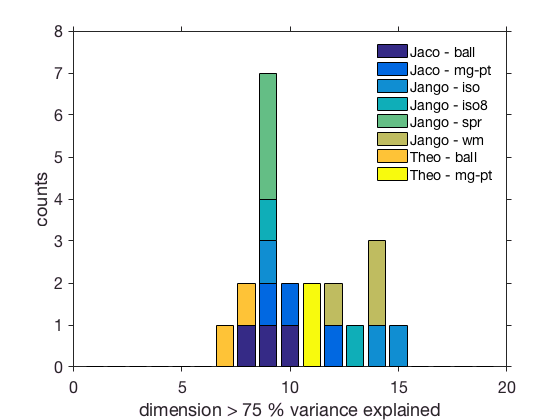

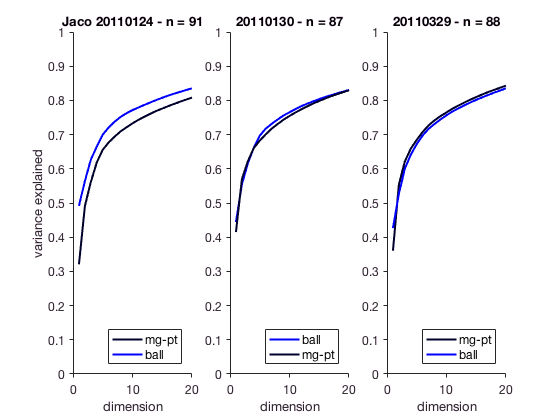

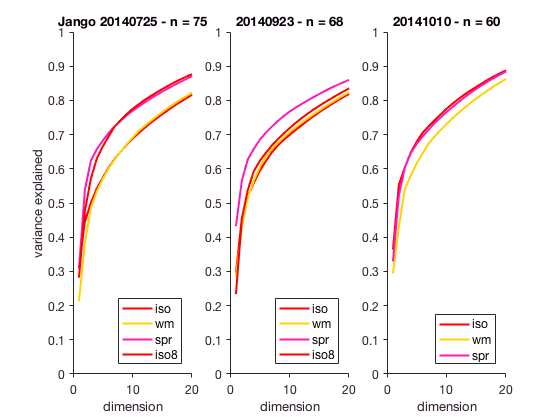

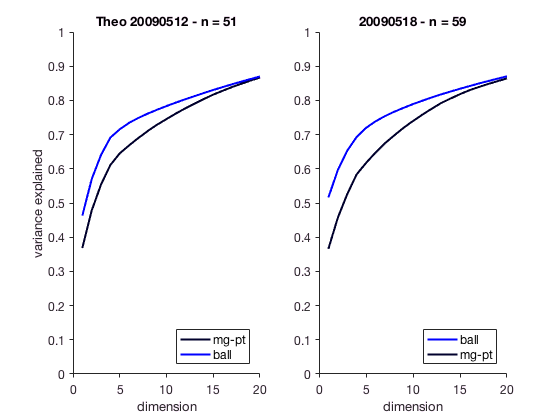

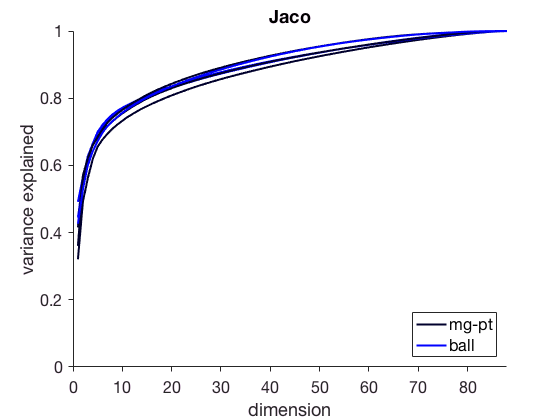

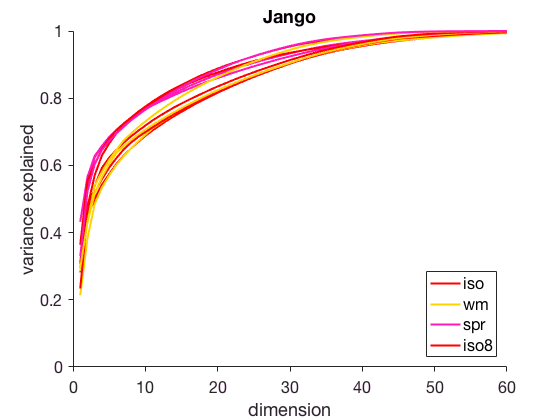

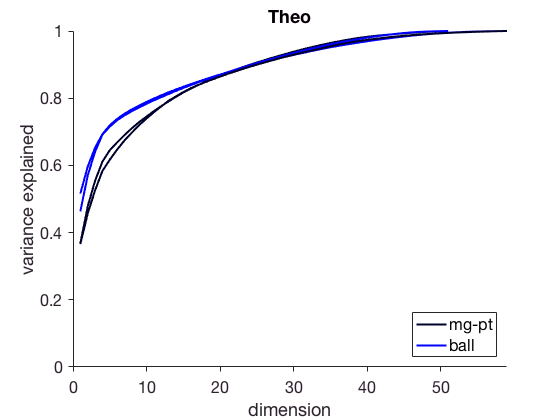


% -------------------------------------------------------------------------
% 1. dimensionality analysis: compare variance explained with PCA, etc
dim_results                     = batch_dimensionality_analysis( datasets );

## Step 3 –Compute principal angles between neural manifolds

This chunk of code computes the *n* leading principal angles between all pairs of manifolds from tasks that the monkey performed in the same session. The number of principal angles, *n*, is the same as the chosen manifold dimensionality.

The significance of the angles, i.e. whether they are smaller than what one would get by chance, is assessed by comparing them to an empirically generated distribution of principal angles.

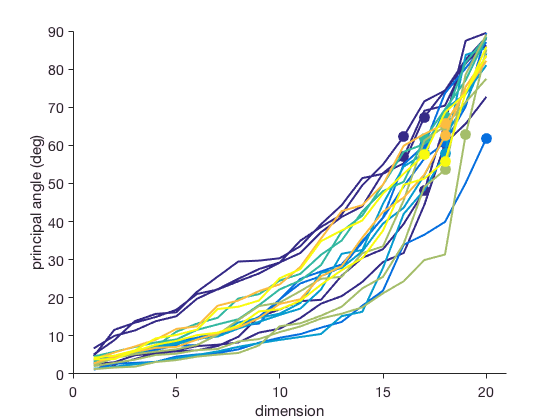

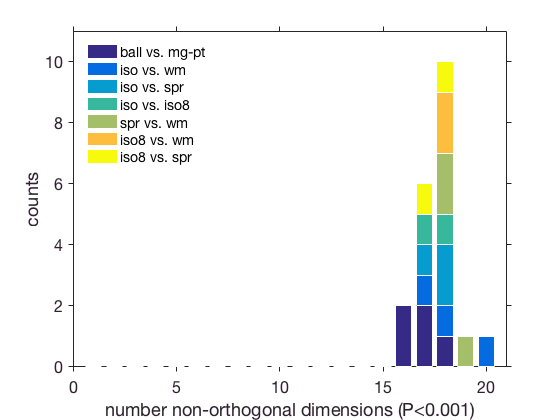


% -------------------------------------------------------------------------
% 2. angles between manifold dimensions
angle_results                   = batch_angle_btw_manifold_dims( datasets );

## Step 4 –Comparing manifold projections (neural dynamics) across tasks

This code compares the neural dynamics by comparing trial-related data across tasks using canonical correlation analysis.

The significance of those CCs is assessed with bootstrapping (the number of bootstraps is defined in `proj_params.nbr_shuffles_bootstrap` and the code takes by default the 99 percentile), and also with Matlab's built-in CCA significance test. Happily, the results of both seem to be in agreement.


% -------------------------------------------------------------------------
% 3. compare the dynamics of the 'neural projections'

% load the default params...
proj_params                     = batch_compare_manifold_projs_defaults();

% increase number of bootstraps, to have a more 'accurate' limit
proj_params.nbr_shuffles_bootstrap = 10000; % instead of the default 1000

% display the windows of trial-related data that will be used for the analysis
% --these values were chosen by hand so the windows have the same length and start 
% approximately where the muscle activity starts
disp(proj_params.time_win)

% and run the analysis
proj_results                    = batch_compare_manifold_projs( datasets, proj_params );

## Step 4 –Comparing potent spaces across tasks

This code fits neuron-to-EMG (or muscle synergy) model to each task, and compares them to assess whether the potent space of M1 is preserved across different behaviors. The model has the form:


$$M=W·N$$



% -------------------------------------------------------------------------
% 4. compute and compare task potent / null spaces

opn_params                      = batch_compare_potent_null_spaces_defaults;

% set a time window that mostly contains movement data
opn_params.time_win             = [ 0.35 1.15; 0.4 1.2; 0.3 1.1;
                                    0 0.7; 0 0.7; 0 0.7; 
                                    0.15 0.95; 0.15 0.95 ];
% number of M1 dimensions that will be used as model inputs
opn_params.dim_neural_manifold  = 10;
% neurons to EMG delay (> 0 => neurons follow)
opn_params.neural_to_output_delay = .05;
% what is the output space? EMGs vs. muscle synergies
opn_params.output               = 'dim_red_emg'; % 'dim_red_emg' 'emg'
opn_params.dim_emg_manifold     = 6;
% use trial averaged data or 'continuous' data?
opn_params.trial_averaged       = true;

% run the analysis
opn_results                     = batch_compare_potent_null_spaces( datasets, opn_params );
